# Quantiles of the Chi-Squared RV

Note: this script supports Section 2.2.6 of **Statistics for Chemical Engineers**: it compares the quantile functions of chi2(1) and N(0,1). Victor Z UW-Madison, 2019 compare chi-squared

clc; clear all; close all hidden;

## Parameters

define parameters

 beta=[2,2,2,2];
alpha=[1/2,2/2,3/2,4/2];
color=["blue","red","green","black"];
x=linspace(0,4,1000);

subplot(2,2,1)
for k=1:length(beta)
plot(x,gampdf(x,alpha(k),beta(k)),color(k),'LineWidth',1.5)
hold on
end
grid on
xlabel('$x$','Interpreter','latex')
ylabel('$f(x)$','Interpreter','latex')
title('')
axis([0,4,0,1])

subplot(2,2,2)
for k=1:length(beta)
plot(x,gamcdf(x,alpha(k),beta(k)),color(k),'LineWidth',1.5)
hold on
end
grid on
lgd=legend('$r=1$','$r=2$','$r=3$','$r=4$','Interpreter','latex','location','southeast')

lgd =   Legend ($r=1$, $r=2$, $r=3$, $r=4$) with properties:

         String: {'$r=1$'  '$r=2$'  '$r=3$'  '$r=4$'}
       Location: 'southeast'
    Orientation: 'vertical'
       FontSize: 7.6500e+00
       Position: [7.5768e-01 6.0188e-01 1.3357e-01 1.5860e-01]
          Units: 'normalized'

  Show all properties

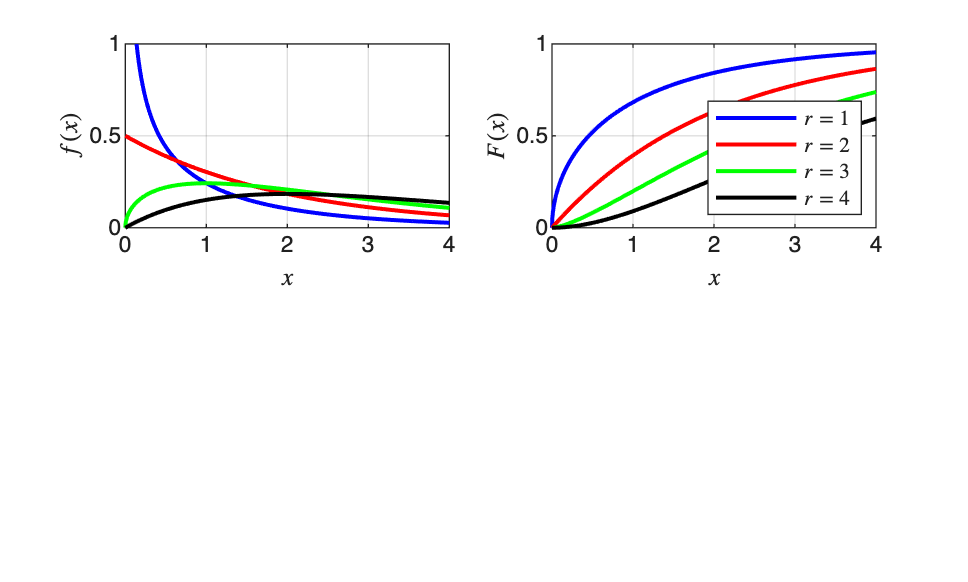

lgd.FontSize = 8;
xlabel('$x$','Interpreter','latex')
ylabel('$F(x)$','Interpreter','latex')
title('')
print -depsc ch2_chisq.eps

## Quantile functions

plot quantile functions for chi2(1) and normal(0,1)

alpha=linspace(0.01,1);
figure(2)
subplot(2,2,1)
plot(alpha,chi2inv(1-alpha,1),'b-','LineWidth',1.5)
grid on
lgd=legend('$\chi^2(1)$','Interpreter','latex','location','northeast')

lgd =   Legend ($\chi^2(1)$) with properties:

         String: {'$\chi^2(1)$'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 7.6500e+00
       Position: [3.1819e-01 8.5464e-01 1.3257e-01 5.1383e-02]
          Units: 'normalized'

  Show all properties

lgd.FontSize = 8;
ylabel('$Q(1-\alpha)$','Interpreter','latex')
xlabel('$\alpha$','Interpreter','latex')
title('')
subplot(2,2,2)
plot(alpha,norminv(1-alpha/2).^2,'b-','LineWidth',1.5)
grid on
lgd=legend('$N(0,1)$','Interpreter','latex','location','northeast')

lgd =   Legend ($N(0,1)$) with properties:

         String: {'$N(0,1)$'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 7.6500e+00
       Position: [7.4480e-01 8.5859e-01 1.4644e-01 4.7431e-02]
          Units: 'normalized'

  Show all properties

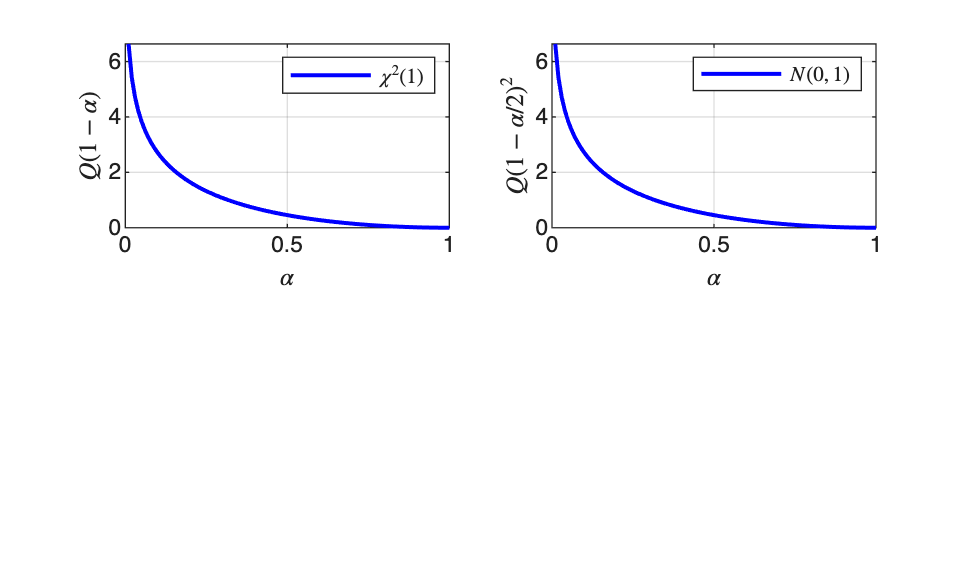

lgd.FontSize = 8;
ylabel('$Q(1-\alpha/2)^2$','Interpreter','latex')
xlabel('$\alpha$','Interpreter','latex')
title('')
print -depsc ch2_quantiles_norm_chi2.eps

## Note

The square of a N(0,1) RV is a chi2(1) RV, so the quantiles of chi2(1) give the critical values of the Gaussian.